%part a
%three precision points chebysev spacing%
theta2 = zeros(1,5)

theta2 =      0     0     0     0     0


for j = 1:3
    theta2(j) = 0.5*(15 + 165) - 0.5 * (165 - 15) * cosd((180*(2*j - 1))/6);
end

%get theta4%
theta4 = 65 + (0.43*theta2);

%solve link length ratios
syms k1 k2 k3
eq1 = k1 * cosd(theta4(1)) - k2 * cosd(theta2(1)) + k3 == cosd(theta2(1) - theta4(1));
eq2 = k1 * cosd(theta4(2)) - k2 * cosd(theta2(2)) + k3 == cosd(theta2(2) - theta4(2));
eq3 = k1 * cosd(theta4(3)) - k2 * cosd(theta2(3)) + k3 == cosd(theta2(3) - theta4(3));
S=solve(eq1,eq2,eq3,k1,k2,k3);
k1 = double(S.k1);
k2 = double(S.k2);
k3 = double(S.k3);
k1A = k1;
k2A = k2;
k3A = k3;

% find missing link lengths
d = 410;
a = abs(d/k1);
c = abs(d/k2);
b = abs(sqrt(a * a + c * c + d * d - 2 * a * c * k3));
fprintf("a %d b %d c %d", a,b,c)

a 5.774377e+01 b 4.424493e+02 c 1.202679e+02

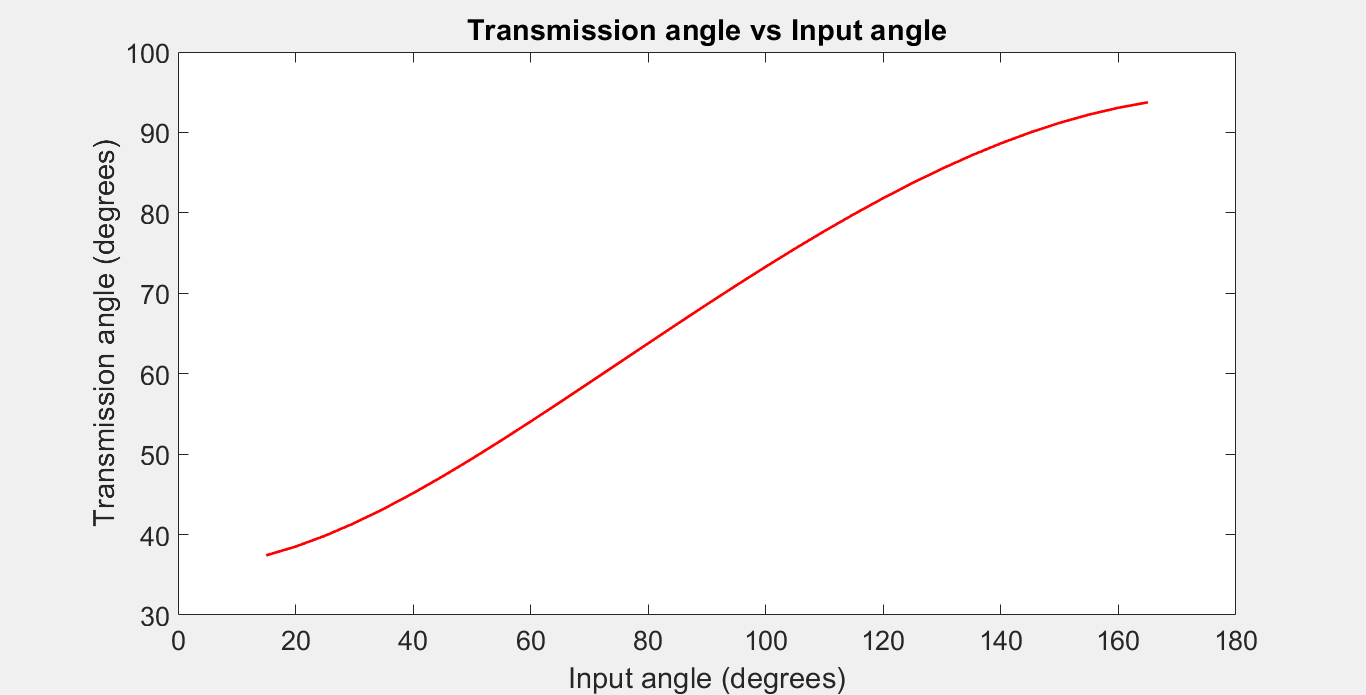

% transmission angle a
inputAngle = 15:5:165;
transAngleA = acosd((b*b + c*c - (a*a+d*d) + 2 * a * d * cosd(inputAngle))/ (2 * b * c));
plot(inputAngle, transAngleA, 'r', 'LineWidth',2)
title('Transmission angle vs Input angle')
xlabel('Input angle (degrees)')
ylabel('Transmission angle (degrees)')
set(gcf,'Position', get(0,'Screensize'));
set(gcf,'Visible','on')
set(gca, 'FontSize', 20)

%part b
%five precision points chebysev spacing%
for j = 1:5
    theta2(j) = 0.5*(15 + 165) - 0.5 * (165 - 15) * cosd((180*(2*j - 1))/10);
end

%get theta4%
theta4 = 65 + (0.43*theta2);

%get k1 k2 k3
A = zeros(3,3)

A =      0     0     0
     0     0     0
     0     0     0


B = zeros(3,1)

B =      0
     0
     0


for i = 1:5
    A(1,1) = A(1,1) + cosd(theta4(i)).^2
    A(1,2) = A(1,2) -cosd(theta4(i)) * cosd(theta2(i))
    A(1,3) = A(1,3) + cosd(theta4(i))
    A(2,1) = A(2,1) + cosd(theta2(i)) * cosd(theta4(i))
    A(2,2) = A(2,2) -cosd(theta2(i)).^2
    A(2,3) = A(2,3) + cosd(theta2(i))
    A(3,1) = A(3,1) + cosd(theta4(i))
    A(3,2) = A(3,2) - cosd(theta2(i))
    A(3,3) = i
    B(1,1) = B(1,1) + cos(theta4(i)) * cos(theta2(i) - theta4(i))
    B(2,1) = B(2,1) + cos(theta2(i)) * cos(theta2(i) - theta4(i))
    B(3,1) = B(3,1) + cos(theta2(i) - theta4(i))
end

A =     0.0852         0         0
         0         0         0
         0         0         0


A =     0.0852   -0.2765         0
         0         0         0
         0         0         0


A =     0.0852   -0.2765    0.2919
         0         0         0
         0         0         0


A =     0.0852   -0.2765    0.2919
    0.2765         0         0
         0         0         0


A =     0.0852   -0.2765    0.2919
    0.2765   -0.8975         0
         0         0         0


A =     0.0852   -0.2765    0.2919
    0.2765   -0.8975    0.9474
         0         0         0


A =     0.0852   -0.2765    0.2919
    0.2765   -0.8975    0.9474
    0.2919         0         0


A =     0.0852   -0.2765    0.2919
    0.2765   -0.8975    0.9474
    0.2919   -0.9474         0


A =     0.0852   -0.2765    0.2919
    0.2765   -0.8975    0.9474
    0.2919   -0.9474    1.0000


B =     0.4165
         0
         0


B =     0.4165
   -0.5719
         0


B =     0.4165
   -0.5719
   -0.5812


A =     0.0936   -0.2765    0.2919
    0.2765   -0.8975    0.9474
    0.2919   -0.9474    1.0000


A =     0.0936   -0.3403    0.2919
    0.2765   -0.8975    0.9474
    0.2919   -0.9474    1.0000


A =     0.0936   -0.3403    0.3835
    0.2765   -0.8975    0.9474
    0.2919   -0.9474    1.0000


A =     0.0936   -0.3403    0.3835
    0.3403   -0.8975    0.9474
    0.2919   -0.9474    1.0000


A =     0.0936   -0.3403    0.3835
    0.3403   -1.3815    0.9474
    0.2919   -0.9474    1.0000


A =     0.0936   -0.3403    0.3835
    0.3403   -1.3815    1.6431
    0.2919   -0.9474    1.0000


A =     0.0936   -0.3403    0.3835
    0.3403   -1.3815    1.6431
    0.3835   -0.9474    1.0000


A =     0.0936   -0.3403    0.3835
    0.3403   -1.3815    1.6431
    0.3835   -1.6431    1.0000


A =     0.0936   -0.3403    0.3835
    0.3403   -1.3815    1.6431
    0.3835   -1.6431    2.0000


B =    -0.0100
   -0.5719
   -0.5812


B =    -0.0100
   -0.7239
   -0.5812


B =    -0.0100
   -0.7239
   -0.1534


A =     0.1497   -0.3403    0.3835
    0.3403   -1.3815    1.6431
    0.3835   -1.6431    2.0000


A =     0.1497   -0.3403    0.3835
    0.3403   -1.3815    1.6431
    0.3835   -1.6431    2.0000


A =     0.1497   -0.3403    0.1467
    0.3403   -1.3815    1.6431
    0.3835   -1.6431    2.0000


A =     0.1497   -0.3403    0.1467
    0.3403   -1.3815    1.6431
    0.3835   -1.6431    2.0000


A =     0.1497   -0.3403    0.1467
    0.3403   -1.3815    1.6431
    0.3835   -1.6431    2.0000


A =     0.1497   -0.3403    0.1467
    0.3403   -1.3815    1.6431
    0.3835   -1.6431    2.0000


A =     0.1497   -0.3403    0.1467
    0.3403   -1.3815    1.6431
    0.1467   -1.6431    2.0000


A =     0.1497   -0.3403    0.1467
    0.3403   -1.3815    1.6431
    0.1467   -1.6431    2.0000


A =     0.1497   -0.3403    0.1467
    0.3403   -1.3815    1.6431
    0.1467   -1.6431    3.0000


B =    -0.4332
   -0.7239
   -0.1534


B =    -0.4332
   -0.9136
   -0.1534


B =    -0.4332
   -0.9136
    0.2700


A =     0.4409   -0.3403    0.1467
    0.3403   -1.3815    1.6431
    0.1467   -1.6431    3.0000


A =     0.4409   -0.7157    0.1467
    0.3403   -1.3815    1.6431
    0.1467   -1.6431    3.0000


A =     0.4409   -0.7157   -0.3929
    0.3403   -1.3815    1.6431
    0.1467   -1.6431    3.0000


A =     0.4409   -0.7157   -0.3929
    0.7157   -1.3815    1.6431
    0.1467   -1.6431    3.0000


A =     0.4409   -0.7157   -0.3929
    0.7157   -1.8655    1.6431
    0.1467   -1.6431    3.0000


A =     0.4409   -0.7157   -0.3929
    0.7157   -1.8655    0.9474
    0.1467   -1.6431    3.0000


A =     0.4409   -0.7157   -0.3929
    0.7157   -1.8655    0.9474
   -0.3929   -1.6431    3.0000


A =     0.4409   -0.7157   -0.3929
    0.7157   -1.8655    0.9474
   -0.3929   -0.9474    3.0000


A =     0.4409   -0.7157   -0.3929
    0.7157   -1.8655    0.9474
   -0.3929   -0.9474    4.0000


B =    -0.8483
   -0.9136
    0.2700


B =    -0.8483
   -1.1383
    0.2700


B =    -0.8483
   -1.1383
    0.6889


A =     0.9299   -0.7157   -0.3929
    0.7157   -1.8655    0.9474
   -0.3929   -0.9474    4.0000


A =     0.9299   -1.3782   -0.3929
    0.7157   -1.8655    0.9474
   -0.3929   -0.9474    4.0000


A =     0.9299   -1.3782   -1.0922
    0.7157   -1.8655    0.9474
   -0.3929   -0.9474    4.0000


A =     0.9299   -1.3782   -1.0922
    1.3782   -1.8655    0.9474
   -0.3929   -0.9474    4.0000


A =     0.9299   -1.3782   -1.0922
    1.3782   -2.7631    0.9474
   -0.3929   -0.9474    4.0000


A =     0.9299   -1.3782   -1.0922
    1.3782   -2.7631         0
   -0.3929   -0.9474    4.0000


A =     0.9299   -1.3782   -1.0922
    1.3782   -2.7631         0
   -1.0922   -0.9474    4.0000


A =     0.9299   -1.3782   -1.0922
    1.3782   -2.7631         0
   -1.0922         0    4.0000


A =     0.9299   -1.3782   -1.0922
    1.3782   -2.7631         0
   -1.0922         0    5.0000


B =    -0.6588
   -1.1383
    0.6889


B =    -0.6588
   -1.0260
    0.6889


B =    -0.6588
   -1.0260
    0.4375


sol = linsolve(A,B);
k1 = sol(1,1)

k1 = -13.2957

k2 = sol(2,1)

k2 = -6.2604

k3 = sol(3,1)

k3 = -2.8169

%get link lengths
d = 410;
a = abs(d/k1);
c = abs(d/k2);
b = abs(sqrt(a * a + c * c + d * d - 2 * a * c * k3));
fprintf("a %d b %d c %d", a,b,c)

a 3.083710e+01 b 4.297882e+02 c 6.549149e+01

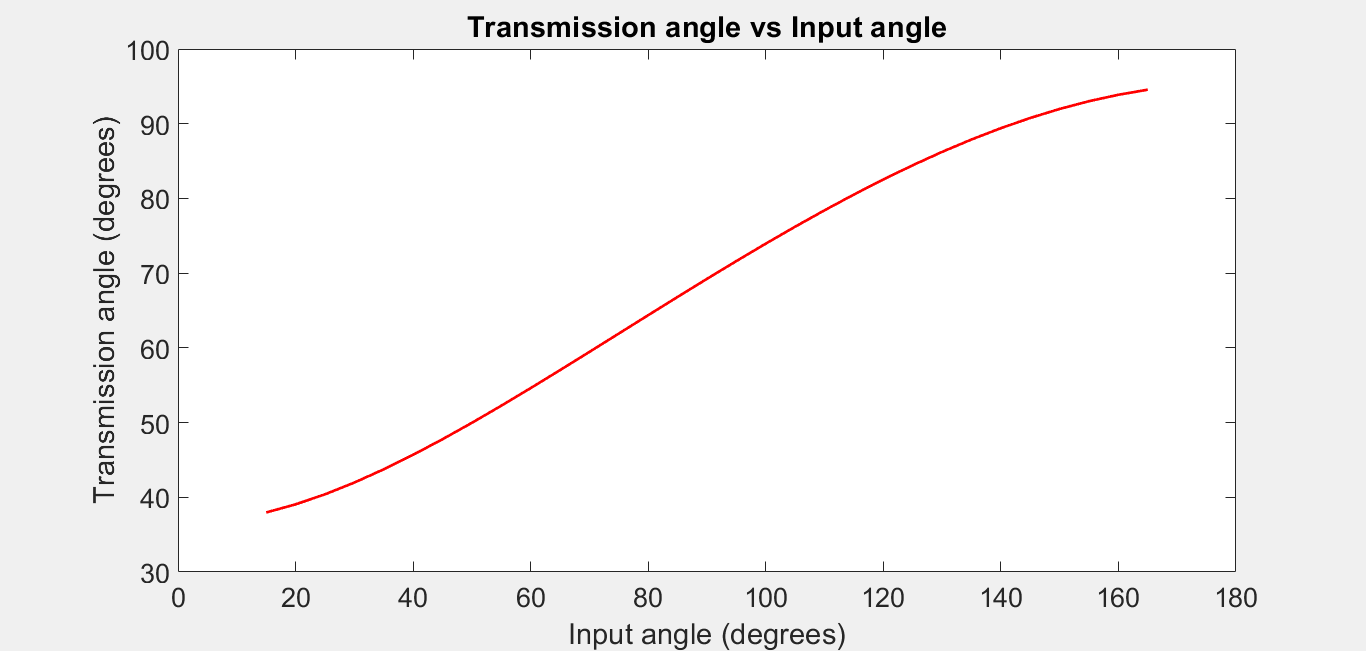

% transmission angle b
inputAngle = 15:5:165;
transAngleB = acosd((b*b + c*c - (a*a+d*d) + 2 * a * d * cosd(inputAngle))/ (2 * b * c));
plot(inputAngle, transAngleB, 'r', 'LineWidth',2)
title('Transmission angle vs Input angle')
xlabel('Input angle (degrees)')
ylabel('Transmission angle (degrees)')
set(gcf,'Position', get(0,'Screensize'));
set(gcf,'Visible','on')
set(gca, 'FontSize', 20)

%comparison graph
ax = plotyy(inputAngle, transAngleA, inputAngle, transAngleB)

ax =   1×2 Axes array:

    Axes    Axes


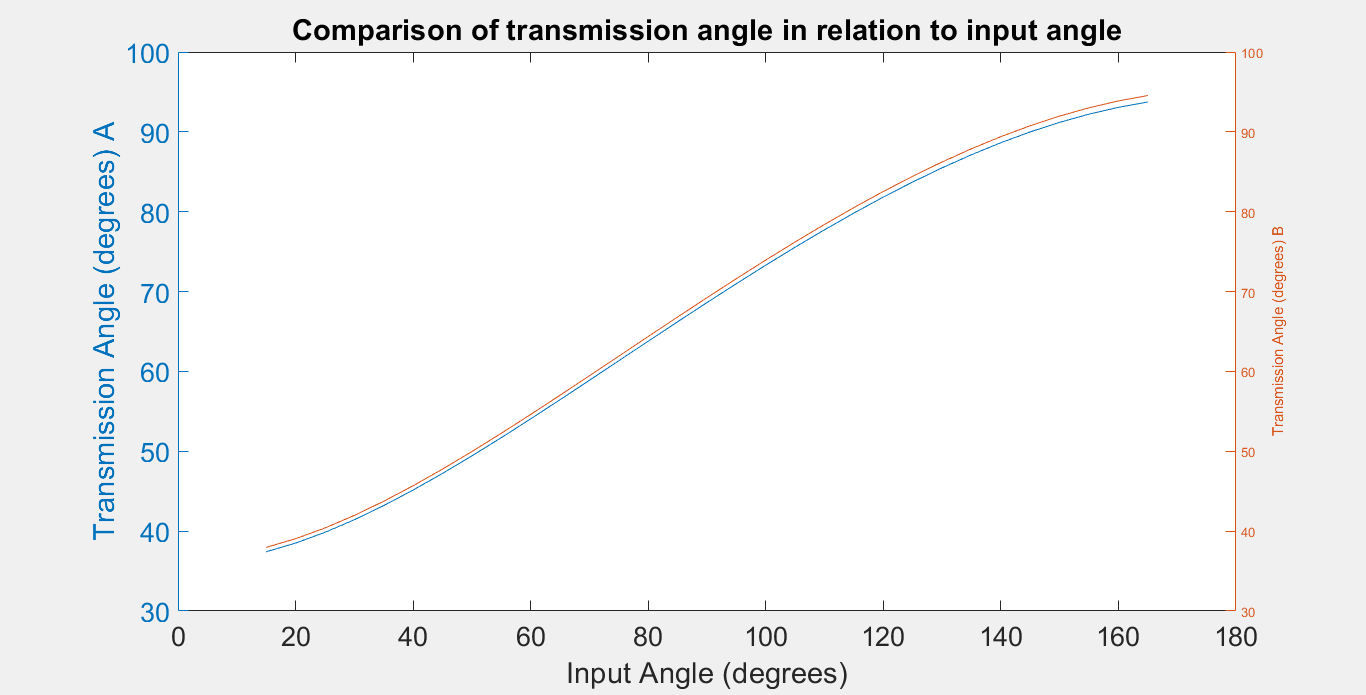

title('Comparison of transmission angle in relation to input angle')
xlabel('Input Angle (degrees)')
ylabel(ax(1), 'Transmission Angle (degrees) A')
ylabel(ax(2), 'Transmission Angle (degrees) B')
set(gcf,'Position', get(0,'Screensize'));
set(gcf,'Visible','on')
set(gca, 'FontSize', 20)

%part c
theta2 = 15:5:165

theta2 =     15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160


theta4 = 65 + (0.43*theta2);
eA = zeros(1,31)

eA =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


eB = zeros(1,31)

eB =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for j = 1:length(theta2)
    eA(j) = k1A * cosd(theta4(j)) - k2A * cosd(theta2(j)) + k3A - cosd(theta2(j) - theta4(j))
    eB(j) = k1 * cosd(theta4(j)) - k2 * cosd(theta2(j)) + k3 - cosd(theta2(j) - theta4(j))
end

eA =    -0.2287         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395         0         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501         0         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133         0         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501   -0.0982         0         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133   -0.7857         0         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501   -0.0982   -0.1425         0         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133   -0.7857   -0.8531         0         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501   -0.0982   -0.1425   -0.1810         0         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133   -0.7857   -0.8531   -0.9121         0         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501   -0.0982   -0.1425   -0.1810   -0.2119         0         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133   -0.7857   -0.8531   -0.9121   -0.9595         0         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501   -0.0982   -0.1425   -0.1810   -0.2119   -0.2336         0         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133   -0.7857   -0.8531   -0.9121   -0.9595   -0.9921         0         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501   -0.0982   -0.1425   -0.1810   -0.2119   -0.2336   -0.2443         0         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133   -0.7857   -0.8531   -0.9121   -0.9595   -0.9921   -1.0067         0         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501   -0.0982   -0.1425   -0.1810   -0.2119   -0.2336   -0.2443   -0.2425         0         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133   -0.7857   -0.8531   -0.9121   -0.9595   -0.9921   -1.0067   -1.0005         0         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501   -0.0982   -0.1425   -0.1810   -0.2119   -0.2336   -0.2443   -0.2425   -0.2267         0         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133   -0.7857   -0.8531   -0.9121   -0.9595   -0.9921   -1.0067   -1.0005   -0.9709         0         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501   -0.0982   -0.1425   -0.1810   -0.2119   -0.2336   -0.2443   -0.2425   -0.2267   -0.1955         0         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133   -0.7857   -0.8531   -0.9121   -0.9595   -0.9921   -1.0067   -1.0005   -0.9709   -0.9154         0         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501   -0.0982   -0.1425   -0.1810   -0.2119   -0.2336   -0.2443   -0.2425   -0.2267   -0.1955   -0.1479         0         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133   -0.7857   -0.8531   -0.9121   -0.9595   -0.9921   -1.0067   -1.0005   -0.9709   -0.9154   -0.8318         0         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501   -0.0982   -0.1425   -0.1810   -0.2119   -0.2336   -0.2443   -0.2425   -0.2267   -0.1955   -0.1479   -0.0827         0         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133   -0.7857   -0.8531   -0.9121   -0.9595   -0.9921   -1.0067   -1.0005   -0.9709   -0.9154   -0.8318   -0.7181         0         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501   -0.0982   -0.1425   -0.1810   -0.2119   -0.2336   -0.2443   -0.2425   -0.2267   -0.1955   -0.1479   -0.0827    0.0009         0


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133   -0.7857   -0.8531   -0.9121   -0.9595   -0.9921   -1.0067   -1.0005   -0.9709   -0.9154   -0.8318   -0.7181   -0.5728         0


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501   -0.0982   -0.1425   -0.1810   -0.2119   -0.2336   -0.2443   -0.2425   -0.2267   -0.1955   -0.1479   -0.0827    0.0009    0.1036


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133   -0.7857   -0.8531   -0.9121   -0.9595   -0.9921   -1.0067   -1.0005   -0.9709   -0.9154   -0.8318   -0.7181   -0.5728   -0.3945


eA =    -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428    0.0983    0.0501         0   -0.0501   -0.0982   -0.1425   -0.1810   -0.2119   -0.2336   -0.2443   -0.2425   -0.2267   -0.1955   -0.1479   -0.0827    0.0009    0.1036


eB =    -1.5523   -1.2814   -1.0486   -0.8527   -0.6926   -0.5664   -0.4724   -0.4084   -0.3718   -0.3601   -0.3703   -0.3994   -0.4442   -0.5015   -0.5678   -0.6395   -0.7133   -0.7857   -0.8531   -0.9121   -0.9595   -0.9921   -1.0067   -1.0005   -0.9709   -0.9154   -0.8318   -0.7181   -0.5728   -0.3945


ax = plotyy(theta2,eA,theta2,eB)
title('Comparison of structural Error in relation to input angle')
xlabel('Input Angle (degrees)')
ylabel(ax(1),'Structural Error in A')
ylabel(ax(2),'Structural Error in B')
set(gcf,'Position', get(0,'Screensize'));
set(gcf,'Visible','on')
set(gca, 'FontSize', 20)